# How many observations should I make? An application of the central limit theorem to human performance variables 

Author: Ross Wilkinson

## Introduction

The central limit theorem states that, under some conditions, the average of many samples (observations) of a random variable with finite mean and variance is itself a random variable – whose distribution converges to a normal distribution as the number of samples increases (Wikipedia).

Thus, we can assume that any measure of human performance will follow a normal distribution and that observations will regress toward a finite mean with a standard normal distribution of variance.

**Example**

We want to compare the maximal 1-s power output produced by a cyclist during a sprint between two different experimental conditions. But we are unsure of how many observations (number of sprints) we should take under each condition. We also want to know whether sprinting indoors on a traditional stationary ergometer is more or less variable than outdoors. 

**Can we take one sample?**

We know that the subject's performance is likely to follow a normal distribution under each condition, so taking one sample (performing one sprint) under each condition has a ~68% chance of being within one standard deviation of their true mean and a ~95% chance of being within two standard deviations, and a ~99% chance of being within three standard deviations. But we have no idea of what the standard deviation is; is it 40 W, 100 W, etc.? and is it more variable on the ergometer or on the bike?

**Can we emprically determine how many observations are sufficient?**

The answer is yes. First, we need to verify that the subject's maximal power output follows a normal distribution; we can do this by taking as many observations as feasibly possible. Once we have an approximation of this distribution we can run simulations to test whether taking a certain number of samples is representative of the mean in the long run.

**Can we empirically determine whether testing on the ergo or on the bike is better?**

Yes again. One way to do this is to calculate the relative uncertainty of the measurement, which in this case be called the relative intra-individual variability. This is done by taking the root mean square error of all the measurements and dividing by the mean. The threshold for an acceptable level of uncertainty will change depending on the measurement.

## Our experiment

We decide that it is feasible for our subject (Ross) to perform 12 sprints, each seperated by 3 minutes of rest, in one testing session without introducing any dependent variables like fatigue. On day 1, Ross performs 12 sprints on a traditional stationary ergometer. On day 2, Ross performs 12 sprints outside on bike. Once we have our results from each day of testing, we will visualize the data, check for any linear trends, fit a distribution, run some simulations to decide on the number of observations we should take, then compare the level of uncertainty between the ergometer and the bike.

## Our results

Here are the results from each day of 12 sprints in Watts.

maxPowerErgo = [1545; 1526; 1526; 1565; 1614; 1544;...
1553; 1611; 1519; 1608; 1571; 1566];

maxPowerBike = [1179; 1145; 1203; 1205; 1201; 1201; 1181;...
    1172; 1221; 1163; 1211; 1171];

## Visualize the data

**Histogram**

A histogram provides a quick visual insight into how a data set is distributed. The range of possible values is divided into intervals, or *bins*. Then a bar chart is created, where the height of each bar corresponds to how frequently values in that bin appear in the data.

Create a histogram of the results seperated into 3 bins.

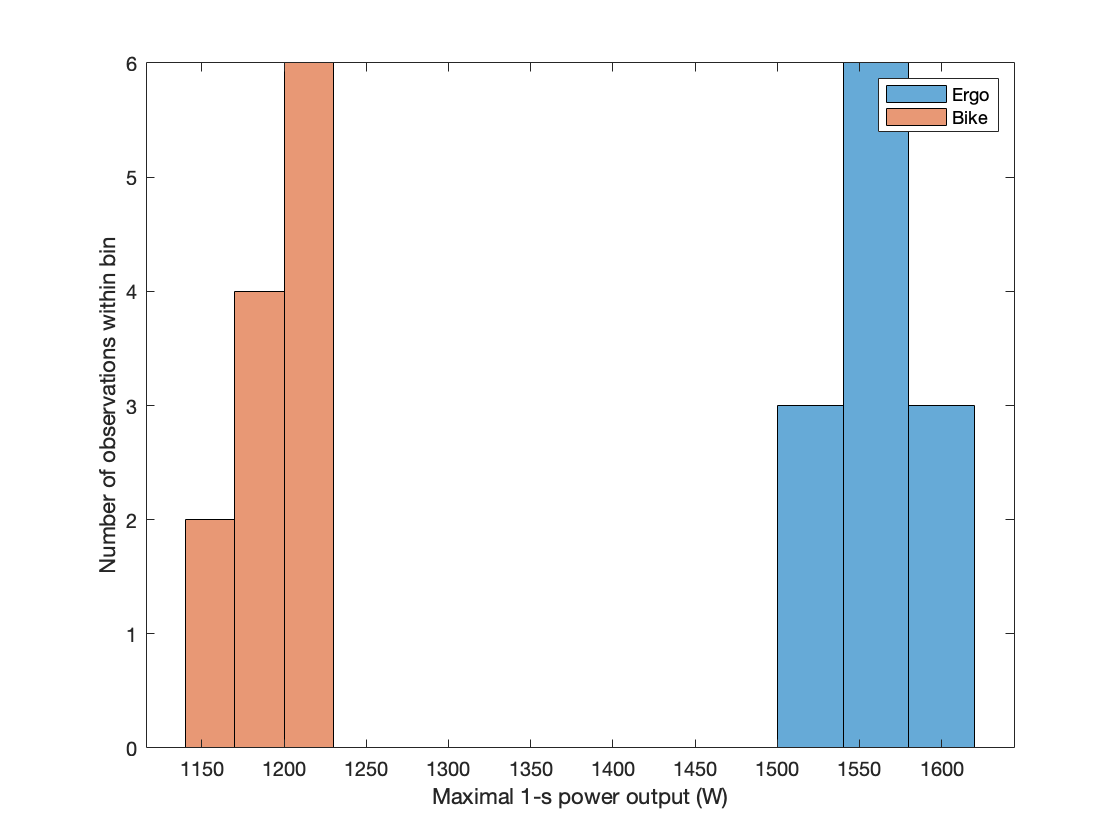

histogram(maxPowerErgo,3)
hold on
histogram(maxPowerBike,3)
hold off
xlabel('Maximal 1-s power output (W)')
ylabel('Number of observations within bin')
legend('Ergo','Bike')

**Scatter plots**

A scatter plot explores how two variables are related to each other. In this case how maximal power output is related to the trial number.

Create a scatter plot of the results across trials 1 to 12.

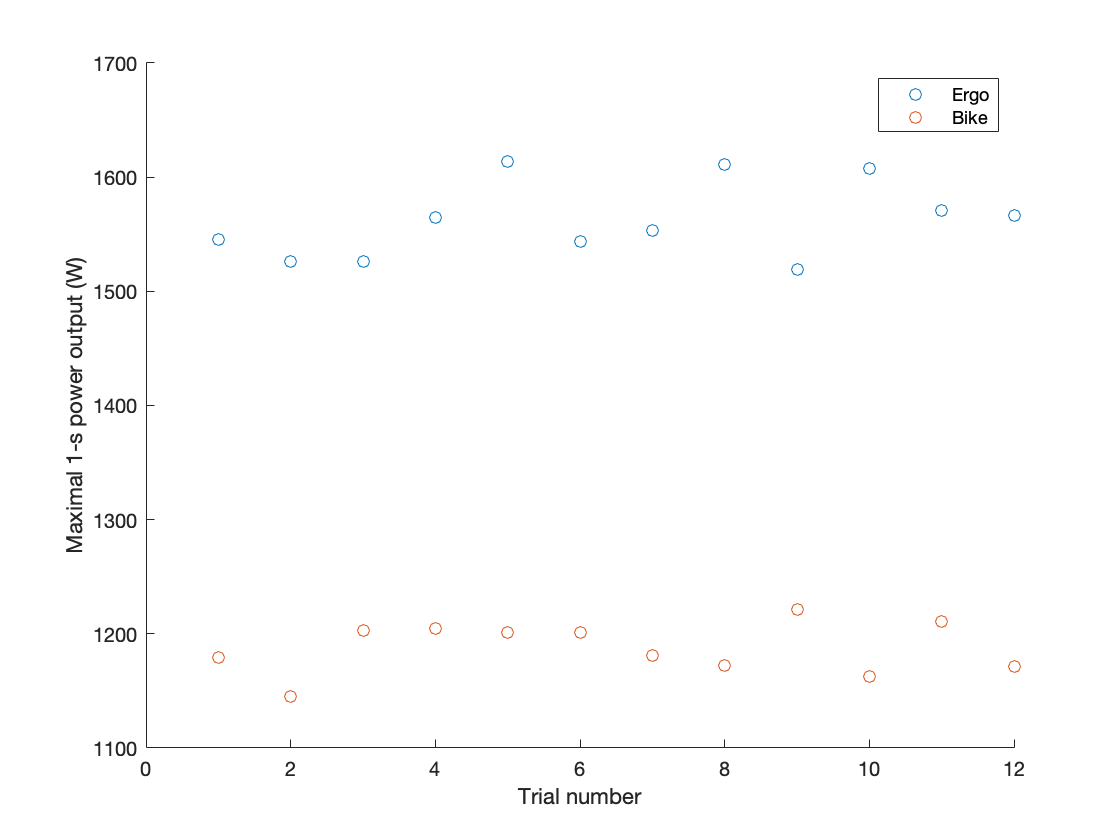

scatter(1:12,maxPowerErgo)
hold on
scatter(1:12,maxPowerBike)
hold off
xlabel('Trial number')
ylabel('Maximal 1-s power output (W)')
legend('Ergo','Bike')

**Box plots**

A box plot is another way to visualize the distribution of a data set. The central box represents the middle 50% of observations, with the red line at the median. The "whisker" lines show the extent of ~99% of the data. Remaining outliers are shown individually with red crosses. 

Create a box plot of the results.

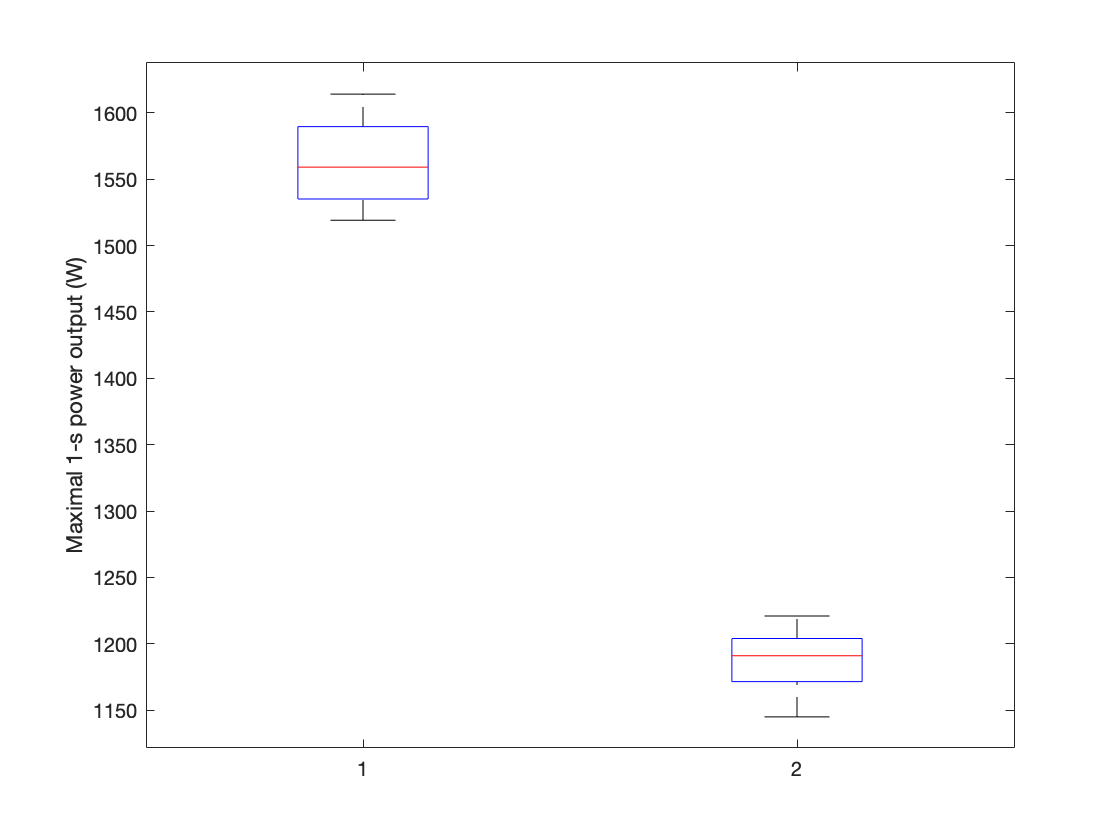

boxplot([maxPowerErgo, maxPowerBike])
ylabel('Maximal 1-s power output (W)')

## Measures of centrality and spread

Calculate the mean and median of the results

meanPwrErgo = mean(maxPowerErgo)

meanPwrErgo = 1.5623e+03

medPwrErgo = median(maxPowerErgo)

medPwrErgo = 1559

meanPwrBike = mean(maxPowerBike)

meanPwrBike = 1.1878e+03

medPwrBike = median(maxPowerBike)

medPwrBike = 1191

Calculate the standard deviation (STD) and interquartile range (IQR) of the results

stdPwrErgo = std(maxPowerErgo)

stdPwrErgo = 33.6569

iqrPwrErgo = iqr(maxPowerErgo)

iqrPwrErgo = 54.5000

stdPwrBike = std(maxPowerBike)

stdPwrBike = 22.5998

iqrPwrBike = iqr(maxPowerBike)

iqrPwrBike = 32.5000

~68% of the results will be within ± one standard deviation from the mean.

50% of the results will be within the IQR from the mean.

## Linear correlation

If we are considering getting our subjects to do less than 12 sprints, then we need to make sure there is no bias as the person performs more sprints.

Test whether there is a significant linear correlation between power output and the number of trials at the significance level 0.05. We are interested in the off-diagonal numbers, which correspond to the r-value and p-value.

nTrials = 1:12;
[rErgo,pErgo] = corrcoef(nTrials',maxPowerErgo)

rErgo =     1.0000    0.3671
    0.3671    1.0000


pErgo =     1.0000    0.2405
    0.2405    1.0000


[rBike,pBike] = corrcoef(nTrials',maxPowerBike)

rBike =     1.0000    0.1110
    0.1110    1.0000


pbike =     1.0000    0.7313
    0.7313    1.0000


A p-value >0.05 confirms that no significant linear correlation exists. Suggesting that taking a smaller number of samples will still provide results that are distributed around the mean.

## Data distribution

Fit and plot a normal distribution then compare it to a fitted distribution.

xErgo = meanPwrErgo-200:meanPwrErgo+200;
xBike = meanPwrBike-200:meanPwrBike+200;
pdfPwrErgo = normpdf(xErgo,meanPwrErgo,stdPwrErgo);
pdfPwrBike = normpdf(xBike,meanPwrBike,stdPwrBike);
% histogram(maxPowerErgo,3,"Normalization","pdf")
% hold on
% histogram(maxPowerBike,3,"Normalization","pdf")
plot(xErgo,pdfPwrErgo,'linewidth',2)
hold on

Fit a kernel distribution to the data

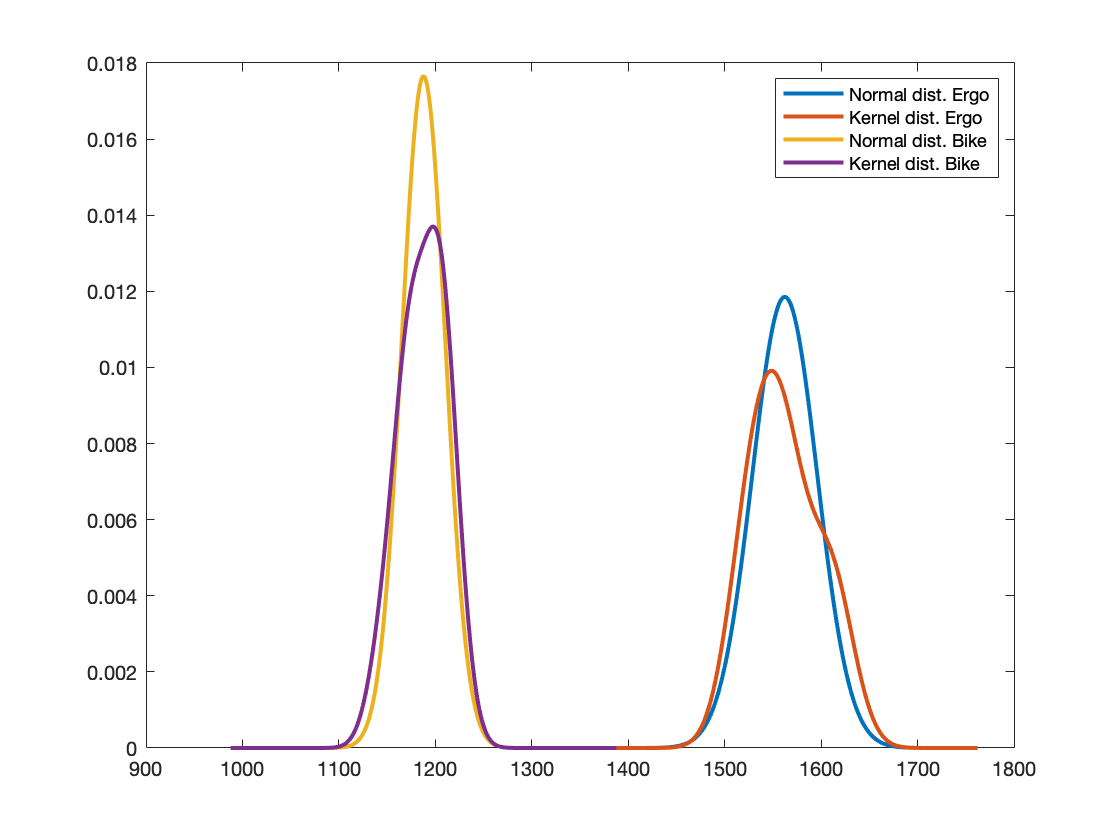

pdErgo = fitdist(maxPowerErgo,'Kernel');
pdBike = fitdist(maxPowerBike,'Kernel');
kerPwrErgo = pdf(pdErgo,xErgo);
kerPwrBike = pdf(pdBike,xBike);
plot(xErgo,kerPwrErgo,'linewidth',2)
plot(xBike,pdfPwrBike,'linewidth',2)
plot(xBike,kerPwrBike,'linewidth',2)
hold off
legend('Normal dist. Ergo','Kernel dist. Ergo','Normal dist. Bike',...
    'Kernel dist. Bike')

Test if the results are significantly different from a standard normal distribution. h = 0 confirms the null.

zErgo = zscore(maxPowerErgo);
zBike = zscore(maxPowerBike);
[hErgo,pErgo] = kstest(zErgo)

hErgo = logical
   0


pErgo = 0.8595

[hBike,pBike] = kstest(zBike)

hBike = logical
   0


pBike = 0.5290

## Run simulations to determine when sampling errors become significant due to performing a smaller number of sprints

As the subject performs less and less sprints the chance that the sample of sprints is different to their true mean becomes greater. We can determine when this error becomes significant by performing a t-test between two samples of a certain size (i.e. if Ross performs 2 rounds of 2 sprints, will the mean of each round of sprints be statistically different from each other?). To see how the chances of this over the long run, we can repeat this t-test 10,000 times using random samples from the predicted distribution. If the samples are similar then 10,000 t-test simulations should provide a uniform distribution of p-values (i.e. the difference is due to chance rather than being systematic).

Let's start by comparing between a sample size of 12 sprints.

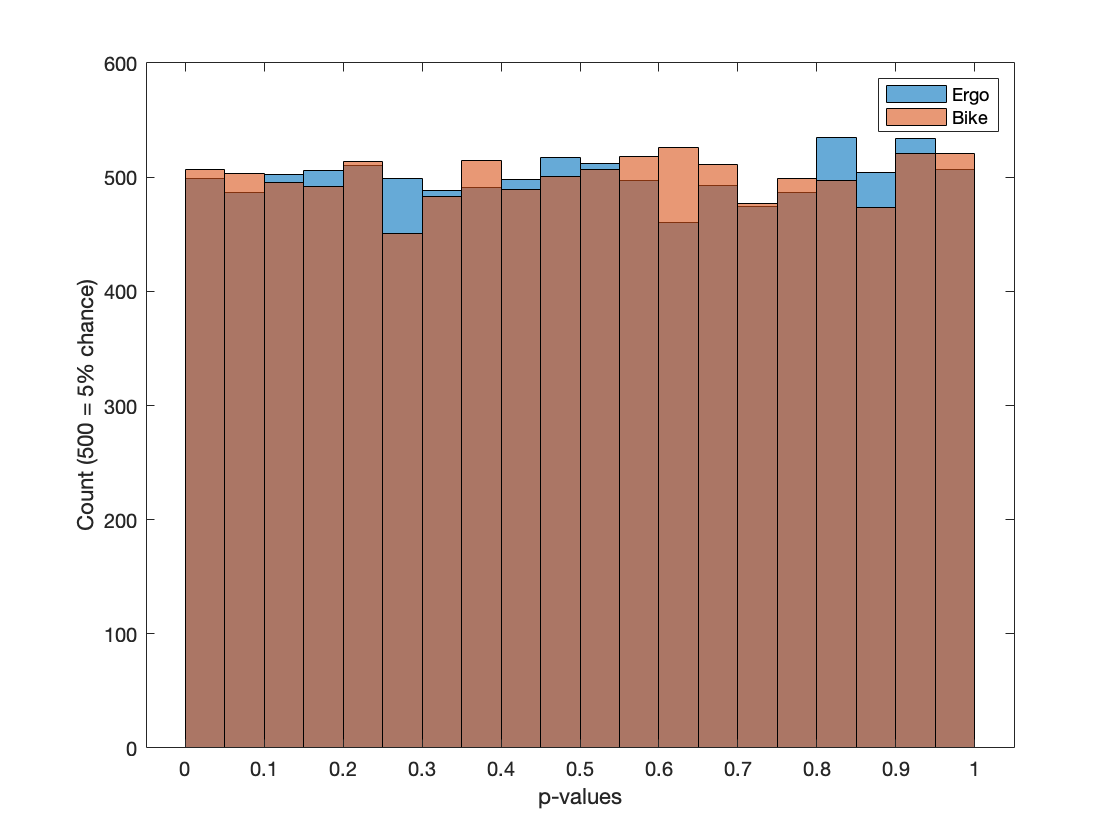

nSamples = 12;
for i = 1:10000
    sample1 = random(pdErgo,nSamples,1);
    sample2 = random(pdErgo,nSamples,1);
    [~,p] = ttest2(sample1,sample2);
    rhoErgo(i) = p;
    sample1 = random(pdBike,nSamples,1);
    sample2 = random(pdBike,nSamples,1);
    [~,p] = ttest2(sample1,sample2);
    rhoBike(i) = p;
end
histogram(rhoErgo,20)
hold on
histogram(rhoBike,20)
hold off
xlabel('p-values')
ylabel('Count (500 = 5% chance)')
legend('Ergo','Bike')

Test if p-value distribution is significantly different from a uniform distribution. h=0 confirms the null.

unipdf = makedist('uniform');
[hErgo,pErgo] = kstest(rhoErgo,'cdf',unipdf)

hErgo = logical
   0


pErgo = 0.3280

[hBike,pBike] = kstest(rhoBike,'cdf',unipdf)

hBike = logical
   0


pBike = 0.8356

As expected the p-value distribution is uniform (random). Now let's try a sample of 3 sprints.

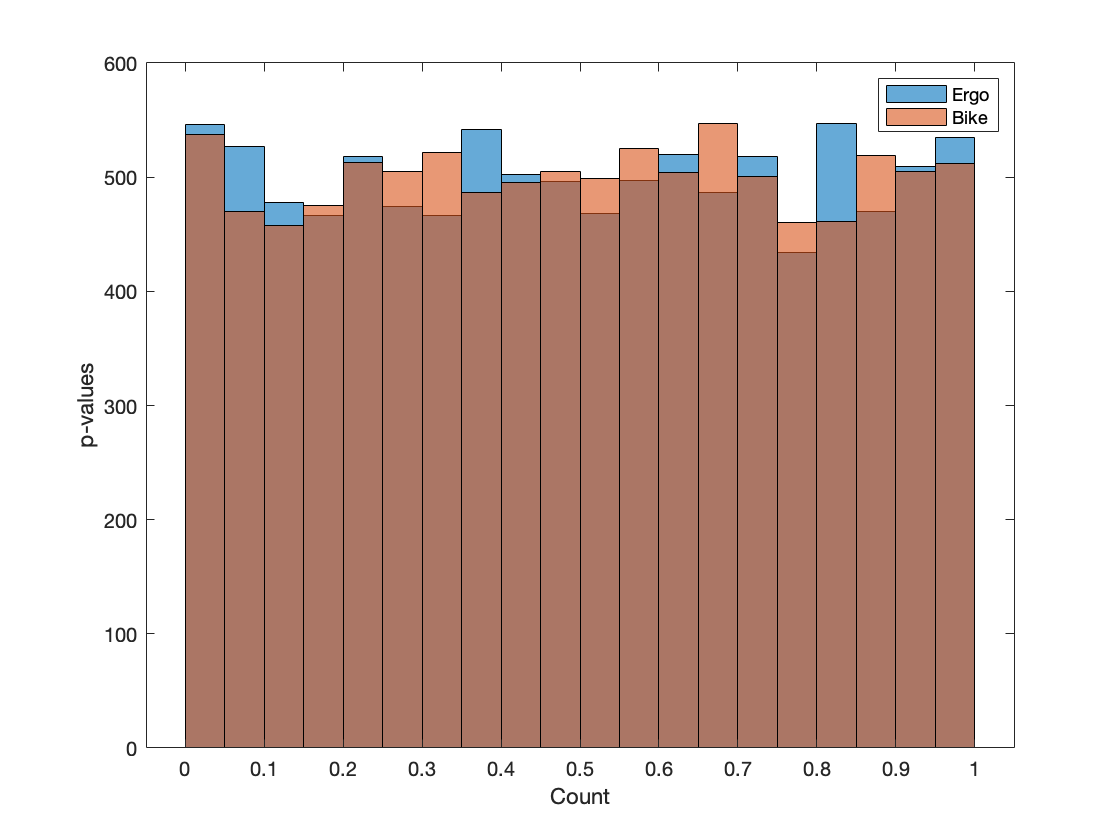

nSamples = 3;
for i = 1:10000
    sample1 = random(pdErgo,nSamples,1);
    sample2 = random(pdErgo,nSamples,1);
    [~,p] = ttest2(sample1,sample2);
    rhoErgo(i) = p;
    sample1 = random(pdBike,nSamples,1);
    sample2 = random(pdBike,nSamples,1);
    [~,p] = ttest2(sample1,sample2);
    rhoBike(i) = p;
end
histogram(rhoErgo,20)
hold on
histogram(rhoBike,20)
hold off
xlabel('Count')
ylabel('p-values')
legend('Ergo','Bike')

Test if p-value distribution is significantly different from a uniform distribution. h=0 confirms the null.

unipdf = makedist('uniform');
[hErgo,pErgo] = kstest(rhoErgo,'cdf',unipdf)

hErgo = logical
   0


pErgo = 0.4285

[hBike,pBike] = kstest(rhoBike,'cdf',unipdf)

hBike = logical
   0


pBike = 0.7662

It appears that getting subjects to perform 3 sprints will still provide an accurate estimation of their true mean.

## Determine the uncertainty of the measurement and how it changes as we collect more sprints

If we assume that the mean over 12 sprints is our best estimate of the true mean, then we can calculate the root mean square error of each batch of measurements (i.e. n=1, n=2, etc.) relative to the mean. We want the uncertainty to be as low as possible, but does this uncertainty increase as we collect less and less measurements? 

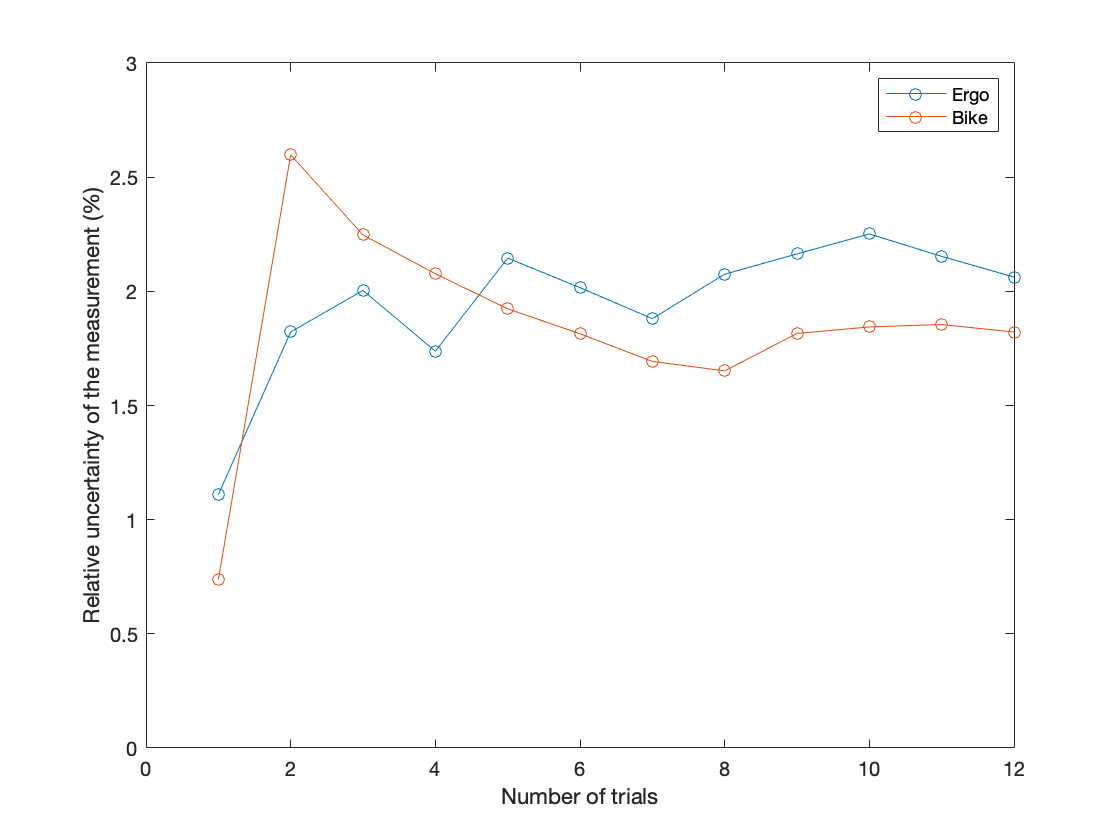

y1rmseErgo = rms(meanPwrErgo - maxPowerErgo(1));
y2rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:2));
y3rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:3));
y4rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:4));
y5rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:5));
y6rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:6));
y7rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:7));
y8rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:8));
y9rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:9));
y10rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:10));
y11rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:11));
y12rmseErgo = rms(meanPwrErgo - maxPowerErgo(1:12));

yErgo = [y1rmseErgo/meanPwrErgo*100; y2rmseErgo/meanPwrErgo*100;...
    y3rmseErgo/meanPwrErgo*100; y4rmseErgo/meanPwrErgo*100;...
    y5rmseErgo/meanPwrErgo*100; y6rmseErgo/meanPwrErgo*100;...
    y7rmseErgo/meanPwrErgo*100; y8rmseErgo/meanPwrErgo*100;...
    y9rmseErgo/meanPwrErgo*100; y10rmseErgo/meanPwrErgo*100;...
    y11rmseErgo/meanPwrErgo*100; y12rmseErgo/meanPwrErgo*100];

y1rmseBike = rms(meanPwrBike - maxPowerBike(1));
y2rmseBike = rms(meanPwrBike - maxPowerBike(1:2));
y3rmseBike = rms(meanPwrBike - maxPowerBike(1:3));
y4rmseBike = rms(meanPwrBike - maxPowerBike(1:4));
y5rmseBike = rms(meanPwrBike - maxPowerBike(1:5));
y6rmseBike = rms(meanPwrBike - maxPowerBike(1:6));
y7rmseBike = rms(meanPwrBike - maxPowerBike(1:7));
y8rmseBike = rms(meanPwrBike - maxPowerBike(1:8));
y9rmseBike = rms(meanPwrBike - maxPowerBike(1:9));
y10rmseBike = rms(meanPwrBike - maxPowerBike(1:10));
y11rmseBike = rms(meanPwrBike - maxPowerBike(1:11));
y12rmseBike = rms(meanPwrBike - maxPowerBike(1:12));

yBike = [y1rmseBike/meanPwrBike*100; y2rmseBike/meanPwrBike*100;...
    y3rmseBike/meanPwrBike*100; y4rmseBike/meanPwrBike*100;...
    y5rmseBike/meanPwrBike*100; y6rmseBike/meanPwrBike*100;...
    y7rmseBike/meanPwrBike*100; y8rmseBike/meanPwrBike*100;...
    y9rmseBike/meanPwrBike*100; y10rmseBike/meanPwrBike*100;...
    y11rmseBike/meanPwrBike*100; y12rmseBike/meanPwrBike*100];

plot(yErgo,'o-')
hold on
plot(yBike,'o-')
hold off
legend('Ergo','Bike')
xlabel('Number of trials')
ylabel('Relative uncertainty of the measurement (%)')
ylim([0 3])

The uncertainty appears to be quite stable between 1.5-2.5% from 3 sprints onwards during both ergometer and outdoor sprints. 